clc; clear; close all
rng("default")

# 1D Cross Section Test

clc; clear; close all
rng("default")

f = @(x, y) 4 + (1 + x.^2 + y.^2).*(sin(2.5*pi*x - 0.5) + cos(2*pi*y - 0.5))

f = function_handle with value:
    @(x,y)4+(1+x.^2+y.^2).*(sin(2.5*pi*x-0.5)+cos(2*pi*y-0.5))


l_theta = @(theta) [2*sin(theta/2), -sin(theta)];

n_lst = 20 * 2.^(2:3)

n_lst =     80   160


h_lst = 0.029 * (1/2).^(2:3);

C2_patches = cell(length(n_lst), 1);
C2_norms = cell(length(h_lst), 1);

% Construct FC Patches
for i=1:2%:length(n_lst)
    n_C2 = n_lst(i);
    h_S = h_lst(i);
    n_S = n_C2; % 10;%ceil(21/20*n_C2);
    
    C2_patch = construct_C2_patch(f, 0.4, 2*pi-0.4, 0, n_C2, n_C2);
    window_patch_xi = construct_S_patch(f, 0.2, 0.42, h_S, n_S, n_S);
    window_patch_eta = construct_S_patch(f, 2*pi-0.2, 2*pi-0.42, h_S, n_S, n_S);
    
    [C2_norm, ~, ~] = C2_patch.compute_phi_normalization(window_patch_xi, window_patch_eta);
    
    C2_patches{i} = C2_patch;
    C2_norms{i} = C2_norm;
    
%     figure;
%     [X, Y] = window_patch_xi.xy_mesh();
%     scatter(X(:), Y(:))   
%     hold on;
%     [X, Y] = C2_patch.xy_mesh();
%     scatter(X(:), Y(:))
%     [X, Y] = window_patch_eta.xy_mesh();
%     scatter(X(:), Y(:))    
%     
%     [XI, ETA] = window_patch_eta.xi_eta_mesh();
%     figure;
%     s = surf(XI, ETA, window_patch_xi.phi(XI, ETA))
end


% 2D
C = 27;
d = 10;

load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

% 1D-FC on each cross section using finest mesh for error

% Computing windowed function on finest mesh
finest_C2_patch = C2_patches{length(n_lst)};
[XI_err, ETA_err] = finest_C2_patch.xi_eta_mesh();

C2_patches

C2_patches = 2×1 cell array
    {1×1 C2_patch_obj}
    {1×1 C2_patch_obj}


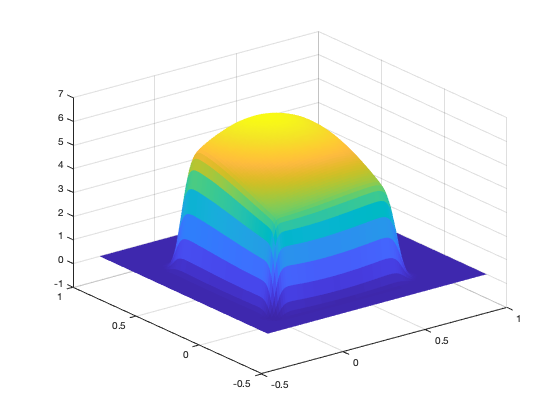


f_exact = finest_C2_patch.f_XY .* finest_C2_patch.phi(XI_err, ETA_err) ./ C2_norms{length(n_lst)};

[h_xi_err, h_eta_err] = finest_C2_patch.h_mesh();

test_patch_i = 1;
% FC and FFT
C2_patch = C2_patches{test_patch_i};
C2_norm = C2_norms{test_patch_i};

% [XI, ETA] = C2_patch.xi_eta_mesh();
% C2_patch.f_XY = C2_patch.f_XY .* C2_patch.phi(XI, ETA);

C2_fcont_patch = C2_patch.FC(C, d, A, Q, C2_norm);
[XI, ETA] = C2_fcont_patch.xi_eta_mesh();
figure;
s = surf(XI, ETA, C2_fcont_patch.f_XY);
s.EdgeColor = 'none';


[h_xi, h_eta] = C2_fcont_patch.h_mesh();
xi_err_mesh = C2_fcont_patch.xi_start:h_xi_err:1+h_xi-h_xi_err;
eta_err_mesh = C2_fcont_patch.eta_start:h_eta_err:1+h_eta-h_eta_err;

n_xi_err = length(xi_err_mesh);
n_eta_err = length(eta_err_mesh);
n_xi_diff = n_xi_err - C2_fcont_patch.n_xi-1;
n_eta_diff = n_eta_err - C2_fcont_patch.n_eta-1;

fc_coeffs = fftshift(fft2(C2_fcont_patch.f_XY)./numel(C2_fcont_patch.f_XY));
padded_fc_coeffs = [zeros(ceil(n_eta_diff/2), n_xi_err); zeros(size(fc_coeffs, 1), ceil(n_xi_diff/2)) fc_coeffs zeros(size(fc_coeffs, 1), floor(n_xi_diff/2)); zeros(floor(n_eta_diff/2), n_xi_err)];
f_numeric = real((n_xi_err*n_eta_err)*ifft2(fftshift(padded_fc_coeffs)));

f_numeric_interior = f_numeric((C*round(h_eta/h_eta_err)+1):(end-round(h_eta/h_eta_err)+1), (C*round(h_xi/h_xi_err)+1):(end-round(h_xi/h_xi_err)+1));

err_mesh = abs(f_numeric_interior-f_exact)

err_mesh =      8.881784197001252e-16     2.280016175859600e-10                         0     2.424727085781342e-10     1.776356839400250e-15     2.573639079628265e-10     8.881784197001252e-16     2.727000847357886e-10                         0     2.885274241748448e-10     8.881784197001252e-16     3.048805652383635e-10     8.881784197001252e-16     3.218110222746873e-10     1.776356839400250e-15     3.393596514911223e-10                         0     3.575895135554674e-10                         0     3.765547873513242e-10                         0     3.963229744385899e-10                         0     4.169704581613587e-10     8.881784197001252e-16     4.385745100421445e-10                         0     4.612283888150159e-10     8.881784197001252e-16     4.850377877119172e-10                         0     5.101128408568911e-10     8.881784197001252e-16     5.365814459423746e-10     8.881784197001252e-16     5.645883760507786e-10     8.881784197001252e-16     5.942997205465872e-10 

err = max(err_mesh, [], 'all')

err =      2.551309078169250e-07


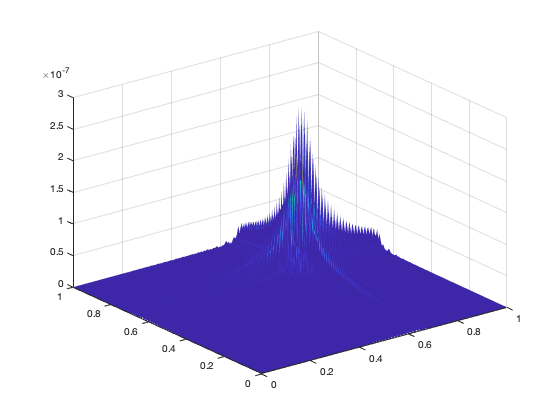


figure;
s = surf(XI_err, ETA_err, err_mesh);
s.EdgeColor = 'none';

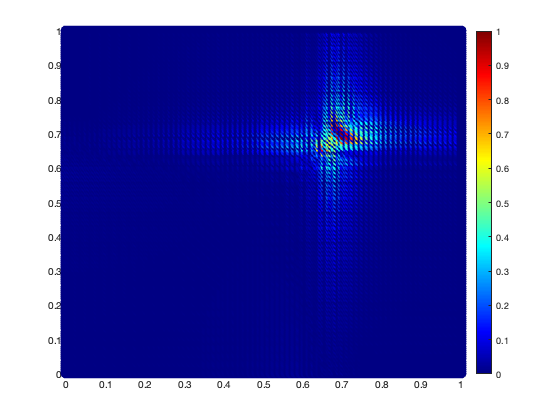


norm_err = err_mesh./err;

figure;
scatter(XI_err(:), ETA_err(:), 100, norm_err(:), 'filled');

% Add a color bar
colorbar;

% Set colormap
colormap(jet);

figure;
surf(XI, ETA, C2_patch.f_XY .* C2_patch.phi(XI, ETA) ./C2_norm)

%1D
err_fixed_xi = zeros(C2_fcont_patch.n_xi+1-C, 1);

% along every vertical 1D cross section that intersects interior
for i = (C+1):(C2_fcont_patch.n_xi+1)
    fc_coeffs = fftshift(fft(C2_fcont_patch.f_XY(:, i)))./numel(C2_fcont_patch.f_XY(:, i));
    padded_fc_coeffs = [zeros(ceil(n_eta_diff/2), 1); fc_coeffs; zeros(floor(n_eta_diff/2), 1)];
    f_numeric = real(n_eta_err*ifft(fftshift(padded_fc_coeffs)));
    
    f_numeric_interior = f_numeric((C*round(h_eta/h_eta_err)+1):(end-round(h_eta/h_eta_err)+1));

    % index of fixed xi in exact solution
    err_fixed_xi(i-C) = max(abs(f_numeric_interior - f_exact(:, (i-C-1)*round(h_eta/h_eta_err)+1)));
end

figure;
plot(linspace(0, 1, length(err_fixed_xi)), err_fixed_xi)

figure;
plot(err_fixed_xi)

err_fixed_eta = zeros(C2_fcont_patch.n_eta+1-C, 1);
% along every vertical 1D cross section that intersects interior
for i = (C+1):(C2_fcont_patch.n_eta+1)
    fc_coeffs = fftshift(fft(C2_fcont_patch.f_XY(i, :)))./numel(C2_fcont_patch.f_XY(i, :));
    padded_fc_coeffs = [zeros(1, ceil(n_xi_diff/2)), fc_coeffs, zeros(1, floor(n_xi_diff/2))];
    f_numeric = real(n_eta_err*ifft(fftshift(padded_fc_coeffs)));
    
    f_numeric_interior = f_numeric((C*round(h_xi/h_xi_err)+1):(end-round(h_xi/h_xi_err)+1));
    
    % index of fixed xi in exact solution
    err_fixed_eta(i-C) = max(abs(f_numeric_interior - f_exact((i-C-1)*round(h_eta/h_eta_err)+1, :)));
end

figure;
plot(linspace(0, 1, length(err_fixed_eta)), err_fixed_eta)

figure;
plot(err_fixed_eta)
hold on;
plot(err_fixed_xi)

[XI, ETA] = C2_fcont_patch.xi_eta_mesh();

i_test = 94+C
figure;
plot(ETA(:, i_test), C2_fcont_patch.f_XY(:, i_test))
hold on;

fc_coeffs = fftshift(fft(C2_fcont_patch.f_XY(:, i_test)))./numel(C2_fcont_patch.f_XY(:, i_test));
padded_fc_coeffs = [zeros(ceil(n_eta_diff/2), 1); fc_coeffs; zeros(floor(n_eta_diff/2), 1)];
f_numeric = real(n_eta_err*ifft(fftshift(padded_fc_coeffs)));

f_numeric_interior = f_numeric((C*round(h_eta/h_eta_err)+1):(end-round(h_eta/h_eta_err)+1));

% index of fixed xi in exact solution
figure;
plot(ETA_err(:, i_test), abs(f_numeric_interior - f_exact(:, (i_test-C-1)*round(h_eta/h_eta_err)+1)))


figure;
plot(ETA_err(:, i_test), f_numeric_interior)
hold on;
plot(ETA_err(:, i_test), f_exact(:, (i_test-C-1)*round(h_eta/h_eta_err)+1))
scatter(ETA(:, i_test), C2_fcont_patch.f_XY(:, i_test))

legend("Numeric", "Exact", "Coarse")

i_test_original = i_test - C;

% [XI, ETA] = C2_patch.xi_eta_mesh();
% XI(:, i_test_original)

% A = [1 1 1 1 1; 5 6 7 8 9; 20 30 42 56 72; 60 120 210 336 504; 120 360 840 1680 3024]
% b = [1; 0; 0; 0; 0]
% 
% A \ b
% phi = @(x) erfc(6*(x))/2;
% figure;
% fplot(phi, [-1, 1])
% 
% figure;
% fplot(phi, [-0.5, 0.5])
% 
% phi(-1)
% phi(1)

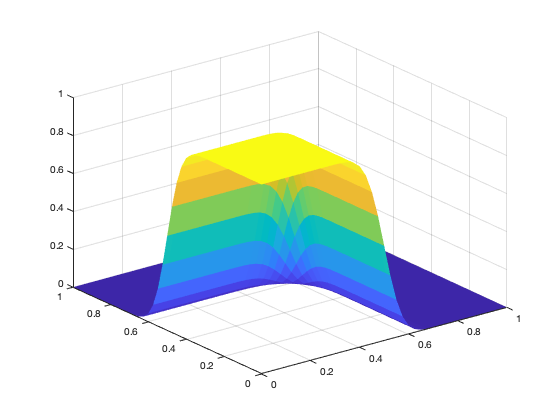

s =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [41×41 double]
           YData: [41×41 double]
           ZData: [41×41 double]
           CData: [41×41 double]

  Show all properties


clc; clear; close all
rng("default")

% 2D
C = 27;
d = 10;

f = @(x, y) x;

n_C2 = 40;

load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

phi_patch = construct_C2_patch(f, 0.4, 2*pi-0.4, 0, n_C2, n_C2);

[XI, ETA] = phi_patch.xi_eta_mesh();
phi_patch.f_XY = phi_patch.phi(XI, ETA);

figure;
s = surf(XI, ETA, phi_patch.f_XY);
s.EdgeColor = 'none'

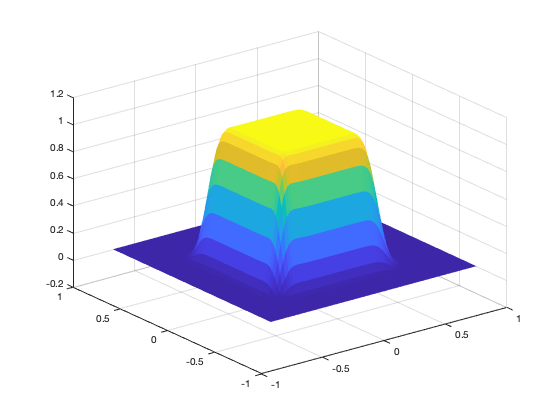

s =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [68×68 double]
           YData: [68×68 double]
           ZData: [68×68 double]
           CData: [68×68 double]

  Show all properties



phi_fcont_patch = phi_patch.FC(C, d, A, Q, nan);

[XI, ETA] = phi_fcont_patch.xi_eta_mesh();

figure;
s = surf(XI, ETA, phi_fcont_patch.f_XY);
s.EdgeColor = 'none'


h_xi_err = 1/(n_C2*8);
h_eta_err = 1/(n_C2*8);

[h_xi, h_eta] = phi_fcont_patch.h_mesh();

[XI_err, ETA_err] = meshgrid(0:h_xi_err:1, 0:h_eta_err:1);
f_exact = phi_patch.phi(XI_err, ETA_err)

f_exact =      1.000000000000000e+00     1.000000000000000e+00     1.000000000000000e+00     1.000000000000000e+00     9.999999999999999e-01     9.999999999999999e-01     9.999999999999999e-01     9.999999999999998e-01     9.999999999999997e-01     9.999999999999994e-01     9.999999999999991e-01     9.999999999999987e-01     9.999999999999979e-01     9.999999999999968e-01     9.999999999999951e-01     9.999999999999927e-01     9.999999999999889e-01     9.999999999999832e-01     9.999999999999748e-01     9.999999999999621e-01     9.999999999999435e-01     9.999999999999157e-01     9.999999999998747e-01     9.999999999998141e-01     9.999999999997253e-01     9.999999999995950e-01     9.999999999994046e-01     9.999999999991269e-01     9.999999999987235e-01     9.999999999981386e-01     9.999999999972933e-01     9.999999999960749e-01     9.999999999943239e-01     9.999999999918143e-01     9.999999999882276e-01     9.999999999831160e-01     9.999999999758515e-01     9.999999999655563e-01  


xi_err_mesh = phi_fcont_patch.xi_start:h_xi_err:1+h_xi-h_xi_err;
eta_err_mesh = phi_fcont_patch.eta_start:h_eta_err:1+h_eta-h_eta_err;

n_xi_err = length(xi_err_mesh);
n_eta_err = length(eta_err_mesh);
n_xi_diff = n_xi_err - phi_fcont_patch.n_xi-1;
n_eta_diff = n_eta_err - phi_fcont_patch.n_eta-1;

fc_coeffs = fftshift(fft2(phi_fcont_patch.f_XY)./numel(phi_fcont_patch.f_XY));
padded_fc_coeffs = [zeros(ceil(n_eta_diff/2), n_xi_err); zeros(size(fc_coeffs, 1), ceil(n_xi_diff/2)) fc_coeffs zeros(size(fc_coeffs, 1), floor(n_xi_diff/2)); zeros(floor(n_eta_diff/2), n_xi_err)];
f_numeric = real((n_xi_err*n_eta_err)*ifft2(fftshift(padded_fc_coeffs)));

f_numeric_interior = f_numeric((C*round(h_eta/h_eta_err)+1):(end-round(h_eta/h_eta_err)+1), (C*round(h_xi/h_xi_err)+1):(end-round(h_xi/h_xi_err)+1));

err_mesh = abs(f_numeric_interior-f_exact)

err_mesh =      2.220446049250313e-16     3.626891120767084e-09     4.931763886162344e-09     4.839185385741018e-09     4.004946263513887e-09     2.875037208305287e-09     1.734910881623364e-09     7.502042320695068e-10     3.330669073875470e-16     4.963934818746907e-10     7.582579009124402e-10     8.270759632722502e-10     7.542261259985139e-10     5.921195755931308e-10     3.882054677717406e-10     1.813333927458416e-10     4.440892098500626e-16     1.379343306240344e-10     2.244391339445428e-10     2.597683179672572e-10     2.504699780914166e-10     2.072264582153593e-10     1.427407081422416e-10     6.985079181731635e-11     1.110223024625157e-16     5.785727452689571e-11     9.788492238982371e-11     1.175362029925964e-10     1.173285912869915e-10     1.003008787137105e-10     7.125544598807210e-11     3.590017172427906e-11     1.110223024625157e-16     3.137001769459857e-11     5.439027006559627e-11     6.683975595223046e-11     6.819822484516180e-11     5.951905635015464e-11 

err = max(err_mesh, [], 'all')

err =      9.863523886544101e-09


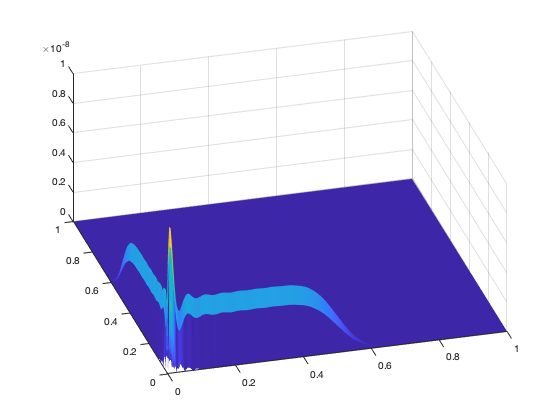


figure;
s = surf(XI_err, ETA_err, err_mesh);
s.EdgeColor = 'none';

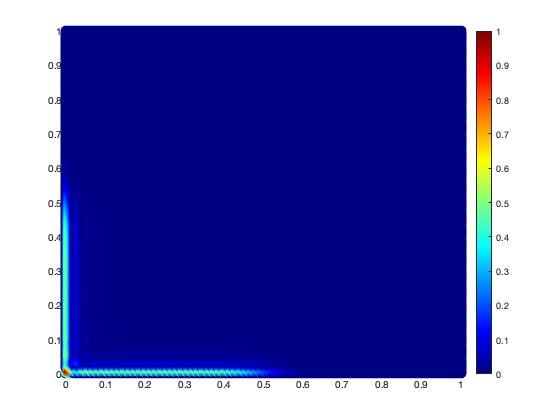


norm_err = err_mesh./err;

figure;
scatter(XI_err(:), ETA_err(:), 100, norm_err(:), 'filled');

% Add a color bar
colorbar;

% Set colormap
colormap(jet);

clc; clear;

C = 27;
d = 10;

load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

f_base = @(x) erfc(6*(-2*x+1))/2;
f1 = @(x) f_base((x-1)/(-1));
f2 = @(x) f_base((x-0.2)/0.6);

f = @(x) f1(x)%./(f1(x)+f2(x))

f = function_handle with value:
    @(x)f1(x)


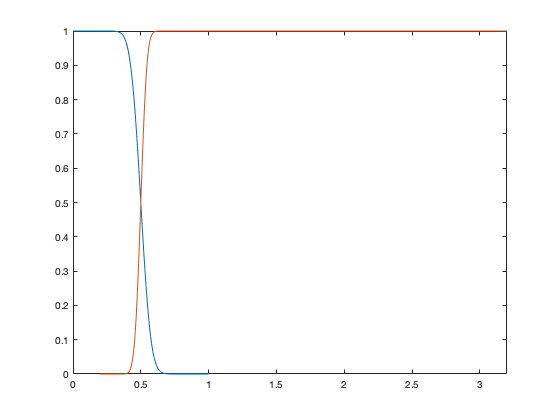


figure;
fplot(f1, [0, 1]);
hold on;
fplot(f2, [0.2, 3.2]);

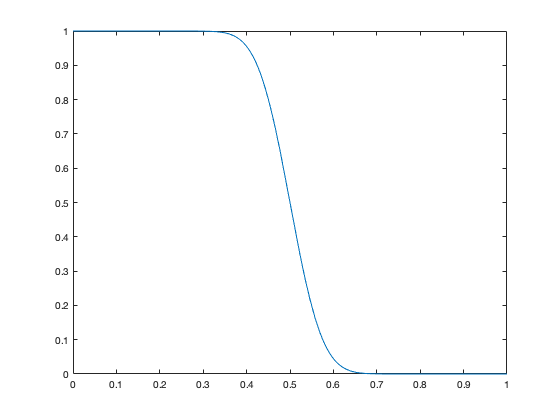


figure;
fplot(f, [0, 1])


figure;
fplot(f1, [0, 1])


n = 80;
h = 1/n;
x_mesh = transpose(linspace(0, 1, n+1));
f_x = f(x_mesh);

fcont = fcont_gram_blend_S(f_x, d, A, Q);
x_mesh_cont = -C*h:h:1;

ncont = length(fcont);

fc_coeffs = fftshift(1/ncont * fft(fcont));

h_err = h*1/5;
err_mesh = transpose(-C*h:h_err:1+h-h_err);
N = length(err_mesh)

N =    540



padded_fc_coeffs = [zeros(ceil((N-ncont)/2), 1); fc_coeffs; zeros(floor((N-ncont)/2), 1)];
f_numeric = N*real(ifft(fftshift(padded_fc_coeffs)));

f_numeric_interior = f_numeric((C*round(h/h_err)+1):(end-round(h/h_err)+1));

err_mesh_interior = transpose(0:h_err:1)

err_mesh_interior =                          0
     2.500000000000000e-03
     5.000000000000000e-03
     7.500000000000000e-03
     1.000000000000000e-02
     1.250000000000000e-02
     1.500000000000000e-02
     1.750000000000000e-02
     2.000000000000000e-02
     2.250000000000000e-02


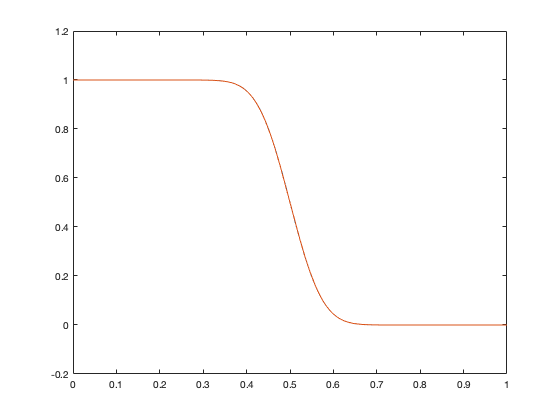


figure;
plot(err_mesh_interior, f_numeric_interior)
hold on;
fplot(f, [0, 1])

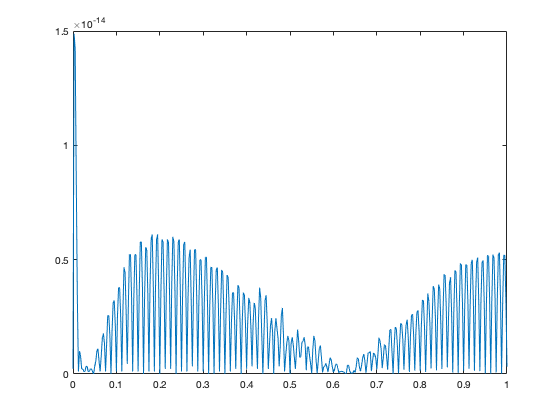


figure;
plot(err_mesh_interior, abs(f_numeric_interior-f(err_mesh_interior)))


max(abs(f_numeric_interior-f(err_mesh_interior)))

ans =      1.487698852997710e-14


function C2_patch = construct_C2_patch(f, theta_A, theta_B, theta_C, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) xi*(theta_A - theta_C) + theta_C;
    l_B = @(eta) eta*(theta_B - theta_C - 2*pi) + theta_C + 2*pi; % account for wrap around
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    J = @(v) [theta_A*cos(v(1)*theta_A/2) (theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2); -theta_A*cos(v(1)*theta_A) -(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p(XI(:), ETA(:));
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    C2_patch = C2_patch_obj(M_p, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, nan); % data associated with patch
end


function S_patch = construct_S_patch(f, theta_A, theta_B, h, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) (theta_B - theta_A)*xi + theta_A;
    nu = @(xi) [cos(l_A(xi)), cos(l_A(xi)/2)] ./ sqrt(cos(l_A(xi)).^2 + cos(l_A(xi)/2).^2);
    
    M_p_general = @(xi, eta, H) l_theta(l_A(xi)) + eta.*H.*nu(xi);
    % H is a function of h and n_eta
    
    theta_diff = theta_B - theta_A;
    J = @(v, H) [theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))), H*cos(l_A(v(1))); -1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2), H*cos(l_A(v(1))/2)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p_general(XI(:), ETA(:), h*n_eta);
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    S_patch = S_patch_obj(M_p_general, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, h, nan);
end
